% Created by: Anthony H. Le
% Last updated: 2022-02-18

% BME 6250 - Biomechanics II
% Homework 3
% Due date: 2022-02-22, 09:00 MST

## Problem 1

close all; clear; clc;

% a)
a0 = transpose([1/sqrt(2) 1/sqrt(2) 0])

a0 =     0.7071
    0.7071
         0



% b)
a0_cross = a0 * transpose(a0)

a0_cross =     0.5000    0.5000         0
    0.5000    0.5000         0
         0         0         0



% (c)
syms lambda1 lambda2 lambda_f

F = diag([lambda1 lambda2 1/(lambda1*lambda2)])

$$F = \left(\begin{array}{ccc} \lambda_{1} & 0 & 0\\ 0 & \lambda_{2} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}\,\lambda_{2}} \end{array}\right)$$

C = transpose(F) * F

$$C = \left(\begin{array}{ccc} {\lambda_{1}}^{2} & 0 & 0\\ 0 & {\lambda_{2}}^{2} & 0\\ 0 & 0 & \frac{1}{{\lambda_{1}}^{2}\,{\lambda_{2}}^{2}} \end{array}\right)$$

J = det(F)

$$J = 1$$

% d)
lambda_f = norm(F * a0)

$$lambda\_f = \sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}$$

a = (F * a0) / lambda_f

$$a = \left(\begin{array}{c} \frac{\sqrt{2}\,\lambda_{1}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ \frac{\sqrt{2}\,\lambda_{2}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ 0 \end{array}\right)$$

% e)
a_cross = a .* transpose(a)

$$a\_cross = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\lambda_{1}}^{2}}{\sigma_{1}} & \frac{\lambda_{1}\,\lambda_{2}}{\sigma_{1}} & 0\\ \frac{\lambda_{1}\,\lambda_{2}}{\sigma_{1}} & \frac{{\lambda_{2}}^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\right) \end{array}$$

% f)$
syms I1 I2 I3 I4 I5 Id c1 c2 c3

Id = eye(3, 3)

Id =      1     0     0
     0     1     0
     0     0     1


F1 = c1 * (I1 - 3)

$$F1 = c_{1}\,\left(I_{1}-3\right)$$

F_lambda = c2 * (exp(c3 * (I4 - 1)^2) - 1)

$$F\_lambda = c_{2}\,\left({\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}-1\right)$$

W = F1 + F_lambda

$$W = c_{2}\,\left({\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}-1\right)+c_{1}\,\left(I_{1}-3\right)$$

dW1 = diff(W, I1)

$$dW1 = c_{1}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = 0$$

dW4 = diff(W, I4)

$$dW4 = c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right)$$

dW5 = diff(W, I5)

$$dW5 = 0$$

dI1 = Id

dI1 =      1     0     0
     0     1     0
     0     0     1


% dI2 = eval(I1 * Id - C)
% dI3 = eval(I3 \ (C))
% dI3 = I2 * Id - I1 * C + C^2
dI4 = a0_cross

dI4 =     0.5000    0.5000         0
    0.5000    0.5000         0
         0         0         0


% dI5 = eval(a0 .* transpose(C) .* a0 + a0 .* C .* transpose(a0))
% g)
% S = 2* ((dW1 + I1 * dW2 + I2 * dW3) * Id - (dW2 + I1 * dW3) * C + dW3 * C^2 + dW4 * a0_cross + dW5 * (a0 .* transpose(C) .* a0 + a0 .* C .* transpose(a0)))
% S = 2 * (dW1 * dI1 + dW2 * dI2 + dW3 * dI3 + dW4 * dI4 + dW5 * dI5)
S = 2 * (dW1 * dI1 + dW4 * dI4)

$$S = \begin{array}{l} \left(\begin{array}{ccc} 2\,c_{1}+\sigma_{1} & \sigma_{1} & 0\\ \sigma_{1} & 2\,c_{1}+\sigma_{1} & 0\\ 0 & 0 & 2\,c_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right) \end{array}$$

T = (1 / J) * F * S * transpose(F)

$$T = \begin{array}{l} \left(\begin{array}{ccc} {\lambda_{1}}^{2}\,\sigma_{1} & \sigma_{2} & 0\\ \sigma_{2} & {\lambda_{2}}^{2}\,\sigma_{1} & 0\\ 0 & 0 & \frac{2\,c_{1}}{{\lambda_{1}}^{2}\,{\lambda_{2}}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,c_{1}+c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right)\\ \sigma_{2}=c_{2}\,c_{3}\,\lambda_{1}\,\lambda_{2}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right) \end{array}$$

p = T(3, 3)

$$p = \frac{2\,c_{1}}{{\lambda_{1}}^{2}\,{\lambda_{2}}^{2}}$$

T = T - p * eye(3, 3)

$$T = \begin{array}{l} \left(\begin{array}{ccc} {\lambda_{1}}^{2}\,\sigma_{1}-\frac{2\,c_{1}}{{\lambda_{1}}^{2}\,{\lambda_{2}}^{2}} & \sigma_{2} & 0\\ \sigma_{2} & {\lambda_{2}}^{2}\,\sigma_{1}-\frac{2\,c_{1}}{{\lambda_{1}}^{2}\,{\lambda_{2}}^{2}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,c_{1}+c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right)\\ \sigma_{2}=c_{2}\,c_{3}\,\lambda_{1}\,\lambda_{2}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right) \end{array}$$

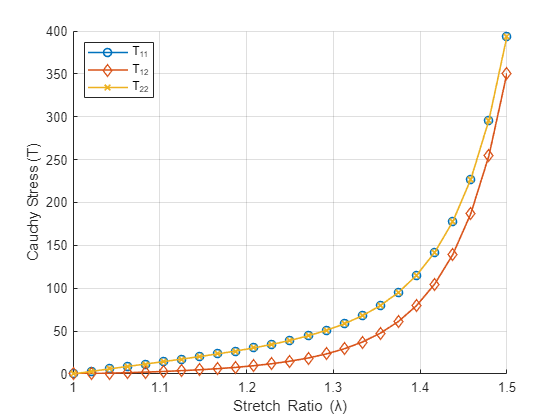

c1 = 10.5; % KPa
c2 = 3.2; % KPa
c3 = 1.6; % unitless

% g) 1
lambda1 = linspace(1, 1.5, 25);
lambda2 = linspace(1, 1.5, 25);

I1 = eval(trace(C));
I4 = eval(lambda_f.^2);

T11_equib = subs(T(1, 1));
T12_equib = subs(T(1, 2));
T22_equib = subs(T(2, 2));

figure();
hold on;
plot(lambda1, T11_equib, '-o', 'LineWidth', 1.2);
plot(lambda1, T12_equib, '-d', 'LineWidth', 1.2);
plot(lambda1, T22_equib, '-x', 'LineWidth', 1.2);
xlabel('Stretch Ratio (\lambda)');
ylabel('Cauchy Stress (T)');
legend('T_{11}', 'T_{12}', 'T_{22}', 'Location', 'northwest');
grid on;
hold off;

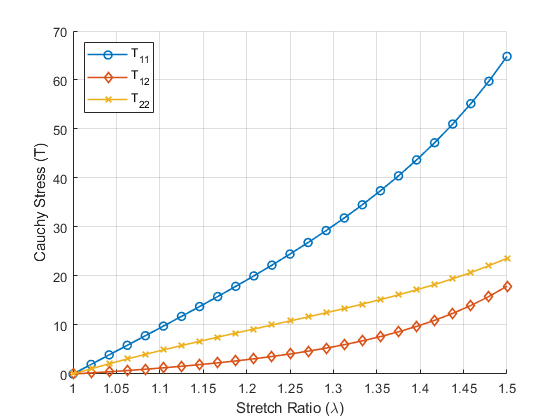

% g) 2
lambda1 = linspace(1, 1.5, 25);
lambda2 = 1;

I1 = eval(trace(C));
I4 = eval(lambda_f.^2);

T11_strip = subs(T(1, 1));
T12_strip = subs(T(1, 2));
T22_strip = subs(T(2, 2));

figure();
hold on;
plot(lambda1, T11_strip, '-o', 'LineWidth', 1.2);
plot(lambda1, T12_strip, '-d', 'LineWidth', 1.2);
plot(lambda1, T22_strip, '-x', 'LineWidth', 1.2);
xlabel('Stretch Ratio (\lambda)');
ylabel('Cauchy Stress (T)');
legend('T_{11}', 'T_{12}', 'T_{22}', 'Location', 'northwest');
grid on;
hold off;

## Problem 2

close all; clear; clc;

syms F1 F2 c1 c2 c3 c4 c5 c6 I1 I2 Id lambda lambda1 lambda2 lambda_s p

Id = diag([1 1 1])

Id =      1     0     0
     0     1     0
     0     0     1



F1 = (c1 / 2) * (I1 - 3) + (c2 / 2) * (I2 - 3)

$$F1 = \frac{c_{1}\,\left(I_{1}-3\right)}{2}+\frac{c_{2}\,\left(I_{2}-3\right)}{2}$$

F2 = piecewise(lambda < 1, 0, lambda < lambda_s, (c3 * (exp(c4 * (lambda - 1)) - 1)), lambda >= lambda_s, (c5 * lambda + c6))

$$F2 = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda <1\\ c_{3}\,\left({\mathrm{e}}^{c_{4}\,\left(\lambda -1\right)}-1\right) & \text{ if }\lambda <\lambda_{s}\\ c_{6}+c_{5}\,\lambda & \text{ if }\lambda_{s}\leq \lambda \end{array}\right.$$

W = F1 + F2

$$W = \left\{ \begin{array}{cl} \frac{c_{1}\,\left(I_{1}-3\right)}{2}+\frac{c_{2}\,\left(I_{2}-3\right)}{2} & \text{ if }\lambda <1\\ c_{3}\,\left({\mathrm{e}}^{c_{4}\,\left(\lambda -1\right)}-1\right)+\frac{c_{1}\,\left(I_{1}-3\right)}{2}+\frac{c_{2}\,\left(I_{2}-3\right)}{2} & \text{ if }\lambda <\lambda_{s}\\ c_{6}+c_{5}\,\lambda +\frac{c_{1}\,\left(I_{1}-3\right)}{2}+\frac{c_{2}\,\left(I_{2}-3\right)}{2} & \text{ if }\lambda_{s}\leq \lambda \end{array}\right.$$

dW1 = diff(F1, I1)

$$dW1 = \frac{c_{1}}{2}$$

dW2 = diff(F1, I2)

$$dW2 = \frac{c_{2}}{2}$$

dW_lambda = F2

$$dW\_lambda = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda <1\\ c_{3}\,\left({\mathrm{e}}^{c_{4}\,\left(\lambda -1\right)}-1\right) & \text{ if }\lambda <\lambda_{s}\\ c_{6}+c_{5}\,\lambda & \text{ if }\lambda_{s}\leq \lambda \end{array}\right.$$

% a)
% uniaxial tension along fiber direction
F_L = diag([1/sqrt(lambda2) lambda2 1/sqrt(lambda2)])

$$F\_L = \left(\begin{array}{ccc} \frac{1}{\sqrt{\lambda_{2}}} & 0 & 0\\ 0 & \lambda_{2} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{2}}} \end{array}\right)$$

B_L = F_L * transpose(F_L)

$$B\_L = \left(\begin{array}{ccc} \frac{1}{\lambda_{2}} & 0 & 0\\ 0 & {\lambda_{2}}^{2} & 0\\ 0 & 0 & \frac{1}{\lambda_{2}} \end{array}\right)$$

J_L = det(F_L)

$$J\_L = 1$$

I1_L = eval(trace(B_L));
I1_L = simplify(I1_L)

$$I1\_L = \frac{{\lambda_{2}}^{3}+2}{\lambda_{2}}$$

I2_L = eval((1/2) * ((trace(B_L))^2 - trace(B_L^2)));
I2_L = simplify(I2_L)

$$I2\_L = \frac{2\,{\lambda_{2}}^{3}+1}{{\lambda_{2}}^{2}}$$

% uniaxial tension transverse to fiber direction
F_T = diag([lambda1 1/sqrt(lambda1) 1/sqrt(lambda1)])

$$F\_T = \left(\begin{array}{ccc} \lambda_{1} & 0 & 0\\ 0 & \frac{1}{\sqrt{\lambda_{1}}} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{1}}} \end{array}\right)$$

B_T = F_T * transpose(F_T)

$$B\_T = \left(\begin{array}{ccc} {\lambda_{1}}^{2} & 0 & 0\\ 0 & \frac{1}{\lambda_{1}} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}} \end{array}\right)$$

J_T = det(F_T)

$$J\_T = 1$$

I1_T = eval(trace(B_T));
I1_T = simplify(I1_T)

$$I1\_T = \frac{{\lambda_{1}}^{3}+2}{\lambda_{1}}$$

I2_T = eval((1/2) * ((trace(B_T))^2 - trace(B_T^2)));
I2_T = simplify(I2_T)

$$I2\_T = \frac{2\,{\lambda_{1}}^{3}+1}{{\lambda_{1}}^{2}}$$

% b)
c6 = -345.4 * 1.046

c6 = -361.2884

% c)
syms WL_lambda WT_lambda
a0 = transpose([0 1 0])

a0 =      0
     1
     0


% uniaxial tension along fiber direction
lambda_L = norm(F_L * a0)

$$lambda\_L = \sqrt{{\left|\lambda_{2}\right|}^{2}}$$

aL = (F_L * a0) / lambda_L

$$aL = \left(\begin{array}{c} 0\\ \frac{\lambda_{2}}{\sqrt{{\left|\lambda_{2}\right|}^{2}}}\\ 0 \end{array}\right)$$

aL_cross = aL * transpose(aL)

$$aL\_cross = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{{\lambda_{2}}^{2}}{{\left|\lambda_{2}\right|}^{2}} & 0\\ 0 & 0 & 0 \end{array}\right)$$

T_L = 2 * ((dW1 + I1_L * dW2) * B_L - dW2 * B_L^2) + lambda2 * WL_lambda * aL_cross

$$T\_L = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & 0 & 0\\ 0 & 2\,{\lambda_{2}}^{2}\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{2}}^{3}+2\right)}{2\,\lambda_{2}}\right)-c_{2}\,{\lambda_{2}}^{4}+\frac{{\mathrm{WL}}_{\lambda }\,{\lambda_{2}}^{3}}{{\left|\lambda_{2}\right|}^{2}} & 0\\ 0 & 0 & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{2}}^{3}+2\right)}{2\,\lambda_{2}}\right)}{\lambda_{2}}-\frac{c_{2}}{{\lambda_{2}}^{2}} \end{array}$$

p_L = T_L(3, 3);
T_L = T_L - p_L * eye(3, 3)

$$T\_L = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 2\,{\lambda_{2}}^{2}\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{2}}^{3}+2\right)}{2\,\lambda_{2}}\right)-\frac{2\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{2}}^{3}+2\right)}{2\,\lambda_{2}}\right)}{\lambda_{2}}+\frac{c_{2}}{{\lambda_{2}}^{2}}-c_{2}\,{\lambda_{2}}^{4}+\frac{{\mathrm{WL}}_{\lambda }\,{\lambda_{2}}^{3}}{{\left|\lambda_{2}\right|}^{2}} & 0\\ 0 & 0 & 0 \end{array}\right)$$

% uniaxial tension transverse to fiber direction
lambda_T = norm(F_T * a0)

$$lambda\_T = \sqrt{\frac{1}{\left|\lambda_{1}\right|}}$$

aT = (F_T * a0) / lambda_T

$$aT = \left(\begin{array}{c} 0\\ \frac{1}{\sqrt{\lambda_{1}}\,\sqrt{\frac{1}{\left|\lambda_{1}\right|}}}\\ 0 \end{array}\right)$$

aT_cross = aT * transpose(aT)

$$aT\_cross = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{1}{\lambda_{1}\,\frac{1}{\left|\lambda_{1}\right|}} & 0\\ 0 & 0 & 0 \end{array}\right)$$

T_T = 2 * ((dW1 + I1_T * dW2) * B_T - dW2 * B_T^2) + lambda1 * WT_lambda * aT_cross

$$T\_T = \begin{array}{l} \left(\begin{array}{ccc} 2\,{\lambda_{1}}^{2}\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{1}}^{3}+2\right)}{2\,\lambda_{1}}\right)-c_{2}\,{\lambda_{1}}^{4} & 0 & 0\\ 0 & \sigma_{1}+\frac{{\mathrm{WT}}_{\lambda }}{\frac{1}{\left|\lambda_{1}\right|}}-\frac{c_{2}}{{\lambda_{1}}^{2}} & 0\\ 0 & 0 & \sigma_{1}-\frac{c_{2}}{{\lambda_{1}}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{1}}^{3}+2\right)}{2\,\lambda_{1}}\right)}{\lambda_{1}} \end{array}$$

p_T = T_T(3, 3);
T_T = T_T - p_T * eye(3, 3)

$$T\_T = \left(\begin{array}{ccc} 2\,{\lambda_{1}}^{2}\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{1}}^{3}+2\right)}{2\,\lambda_{1}}\right)-\frac{2\,\left(\frac{c_{1}}{2}+\frac{c_{2}\,\left({\lambda_{1}}^{3}+2\right)}{2\,\lambda_{1}}\right)}{\lambda_{1}}+\frac{c_{2}}{{\lambda_{1}}^{2}}-c_{2}\,{\lambda_{1}}^{4} & 0 & 0\\ 0 & {\mathrm{WT}}_{\lambda }\,\left|\lambda_{1}\right| & 0\\ 0 & 0 & 0 \end{array}\right)$$

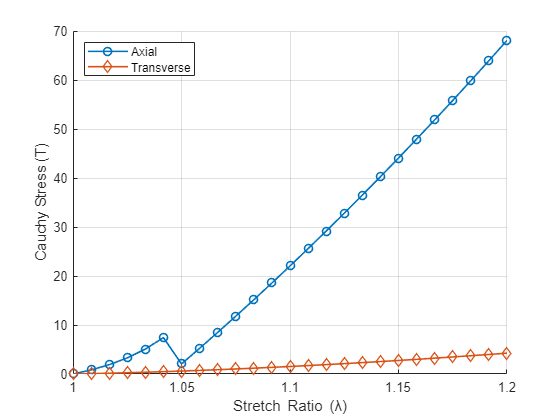

% experimental data
c1 = 28.1; % MPa
c2 = -25.3; % MPa
c3 = 2.5; % MPa
c4 = 31.2; % unitless
c5 = 345.4; % MPa
lambda_s = 1.046; % unitless

WL_lambda = piecewise(lambda2 < 1, 0, lambda2 < lambda_s, (c3 * (exp(c4 * (lambda2 - 1)) - 1)), lambda2 >= lambda_s, (c5 * lambda2 + c6));
WT_lambda = piecewise(lambda1 < 1, 0, lambda1 < lambda_s, (c3 * (exp(c4 * (lambda1 - 1)) - 1)), lambda1 >= lambda_s, (c5 * lambda1 + c6));

WL_lambda = eval(WL_lambda);
WT_lambda = eval(WT_lambda);

lambda1 = linspace(1, 1.2, 25);
lambda2 = linspace(1, 1.2, 25);

WL_lambda = subs(WL_lambda);
WT_lambda = subs(WT_lambda);

% d)
T_L_22 = subs(T_L(2, 2));
T_T_11 = subs(T_T(1, 1));

figure();
hold on;
plot(lambda2, T_L_22, '-o', 'LineWidth', 1.2);
plot(lambda1, T_T_11, '-d', 'LineWidth', 1.2);
xlabel('Stretch Ratio (\lambda)');
ylabel('Cauchy Stress (T)');
legend('Axial', 'Transverse', 'Location', 'northwest');
grid on;
hold off;